offset = 2.5000

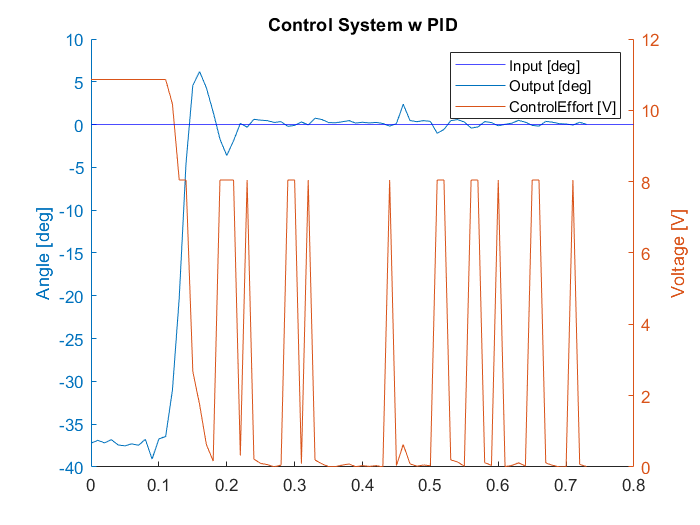

%save("MotorY_PID_corrected.mat")

%load MotorY_PID.mat

%
%t_Y_PID = out.tout;
%input_Y_PID = out.simout4.Data;
%error_Y_PID = out.simout5.Data;
%CE_Y_PID = out.simout6.Data;
%offset = 2.5
%output_Y_PID = out.simout7.Data-offset;

%GY = 3;
%CE_Y_PID = (11.4/255)*GY*CE_Y_PID;

load MotorY_PID_corrected.mat

clf;
hold on
yyaxis left
yline(0,'b')
plot(t_Y_PID,output_Y_PID)
ylabel('Angle [deg]')
ylim([-40 10])


yyaxis right
plot(t_Y_PID,CE_Y_PID)
ylabel('Voltage [V]')
title('Control System w PID')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off

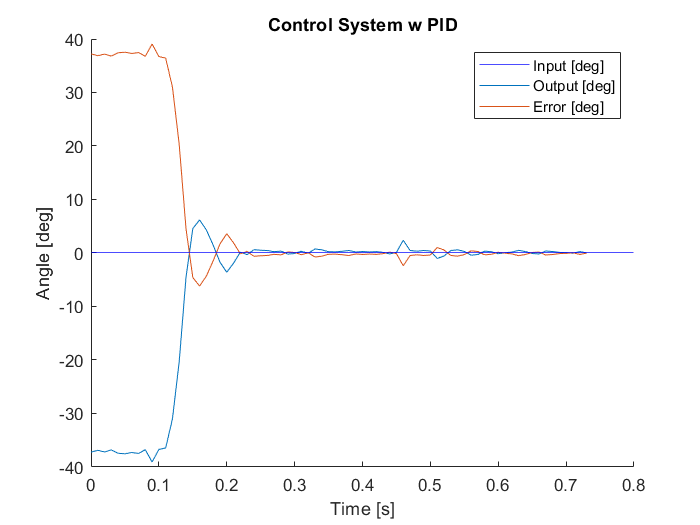

clf;
hold on
yline(0,'b')
plot(t_Y_PID,output_Y_PID)
ylabel('Angle [deg]')
xlabel('Time [s]')
ylim([-40 40])
plot(t_Y_PID,error_Y_PID)
title('Control System w PID')
legend('Input [deg]','Output [deg]','Error [deg]')

hold off